# 日本の標高データをMATLABで活用 - GeoTiff変換 -

## はじめに

やっほー、HerniaBabyです。

みんなはこのWebセミナーを見たことがありますか？

[RoadRunner:日本の空中写真・標高データ活用法](https://jp.mathworks.com/videos/roadrunner-how-to-import-japanese-aerial-and-elevation-images-1629895701730.html)

けっこう革新的で素晴らしい動画なんだけどひとつだけ気にくわないところがあります。

それはこれ

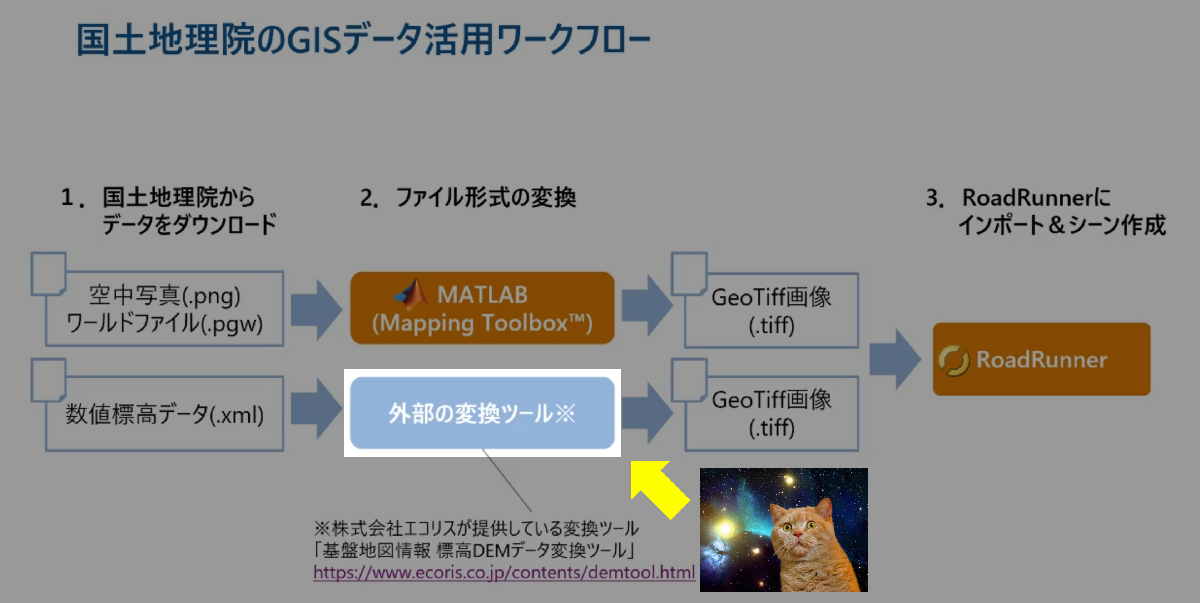

**え？！なんで外部ツール使うん？！**

**Mapping Toolboxあるやろ！**

てなわけで、今回は国土地理院の数値標高データ(.xml)を自分でGeoTiff画像にします。

(このためにMapping Toolbox買いました。)

## データを入手する

数値標高モデルについては[基盤地図情報ダウンロードサイト](https://fgd.gsi.go.jp/download/menu.php)から好きな場所をダウンロードしてください。

今回の題材として、メッシュ番号5841-46を選択して1mメッシュの航空レーザ測量データを使用します。

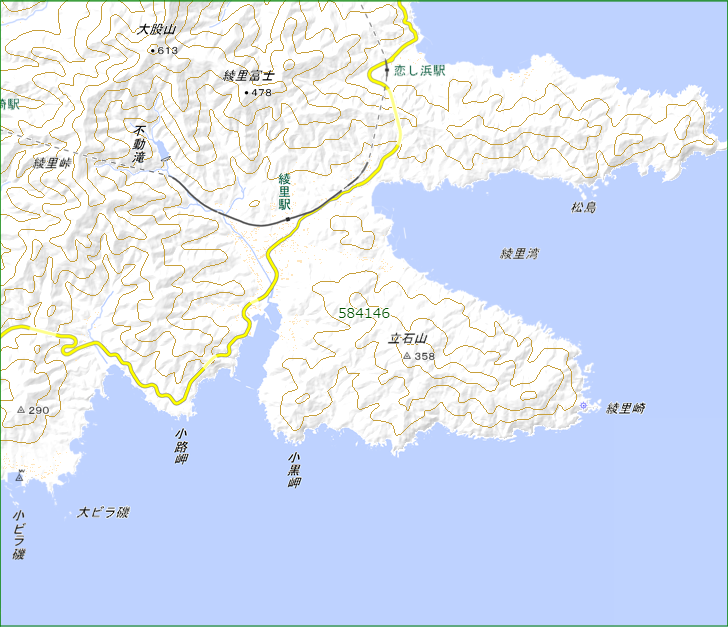

※2023年11月30日(木)より、最新の航空レーザ測量データを基に作成した**１ｍメッシュデータ**が提供されるようになりました。

　いやあ、すごいっすね！詳細リンクは[**こちら**](https://www.gsi.go.jp/gazochosa/gazochosa61002.html)！

## データの構成について

データの構成に関しては以下を参考にしました。

[基盤地図情報～数値標高モデルを利用する](https://qiita.com/tobira-code/items/43a23362f356198adce2)

### フォーマット

　FG-GML-pppp-qq-rr-DEM5X-yyyymmdd.xml

- pppp:           1次メッシュ番号

- qq:               2次メッシュ番号

- rr:                 3次メッシュ番号

- X:                 測量方法(A = レーザー測量, B = 写真測量)…※

- yyyymmdd:  年月日

#### フォーマット例

*　FG-GML-5841-46-00-DEM1A-20230929.xml*

　※今回は1mメッシュの航空レーザ測量なので1Aになっています。

### メッシュ番号

メッシュ番号については[地域メッシュ統計(総務省統計局)](https://www.stat.go.jp/data/mesh/index.htm)がわかりやすいです。

[第１章 地域メッシュ統計の特質・沿革 (9頁目)](https://www.stat.go.jp/data/mesh/pdf/gaiyo1.pdf#page=9) 

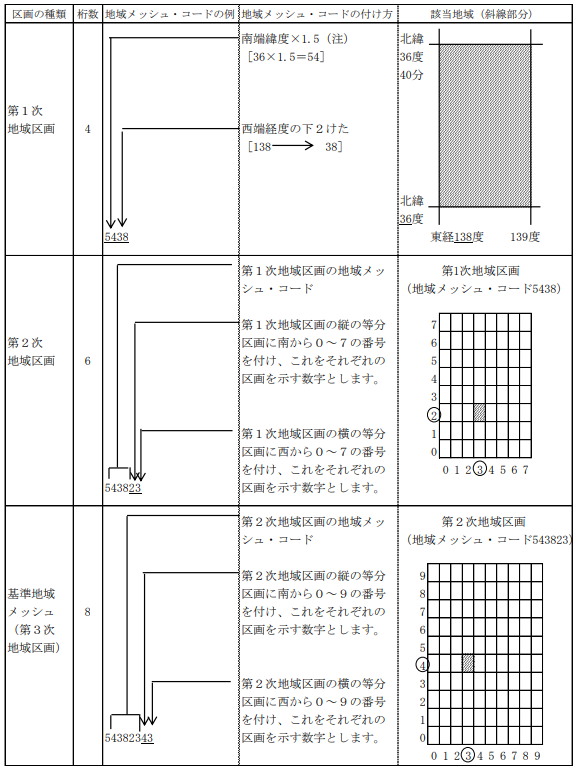

本記事では**3次メッシュを1つずつGeoTiffデータにする**というものです。

## 3次メッシュデータを読みこんでみよう

まずはひとつデータを読み込んでみましょうか。

xmlファイルは [readstruct](https://jp.mathworks.com/help/matlab/ref/readstruct.html) から読み込むことができます。

clear,clc;
% file_name = '\PackDLMap\FG-GML-5841-46-DEM1A\FG-GML-5841-46-00-DEM1A-20230929.xml';
% T = readstruct(file_name,'FileType','xml');

% 任意のファイルを使う場合はこちら
[file_name, path] = uigetfile('*.xml');
T = readstruct(fullfile(path,file_name),'FileType','xml');

データ自体は T.DEM にあります。中身を見てみましょう。

### 緯度経度の範囲

`lowerCornerで北西端、upperCornerで南東端の緯度経度をとってきます。`

`ここから範囲を決めることができるわけですね。`

disp(T.DEM.coverage.gml_boundedBy.gml_Envelope)

    srsNameAttribute: "fguuid:jgd2011.bl"
     gml_lowerCorner: "39 141.75"
     gml_upperCorner: "39.008333333 141.7625"



### メッシュを構成するグリッドセルの配列数

GridEnvelopeに入ってます。セルを何分割して標高データを入れてるかですね。

low属性は北西端を示す番号です。常に(0,0)です。

high属性は南東端を示す番号です。5mメッシュは(224,149)、1m & 10mメッシュは(1124,749)固定です。

disp(T.DEM.coverage.gml_gridDomain.gml_Grid.gml_limits.gml_GridEnvelope)

     gml_low: "0 0"
    gml_high: "1124 749"



### 標高データ

tupleListに入っています。[splitlines](https://jp.mathworks.com/help/matlab/ref/splitlines.html) で改行部分で分割し一部見てみましょう。

水面や標高データがない場合は、標高の値が -9999 になります。

Surf = splitlines(T.DEM.coverage.gml_rangeSet.gml_DataBlock.gml_tupleList);
disp(Surf(1:5))

    "海水面,-9999."
    "海水面,-9999."
    "海水面,-9999."
    "海水面,-9999."
    "海水面,-9999."



### データの並べ方

orderAttributeに入ってます。データをどういう風に並べるか決めています。

以下引用([基盤地図情報～数値標高モデルを利用する](https://qiita.com/tobira-code/items/43a23362f356198adce2)より原文ママ)

*　orderの"+x"はxが正の方向(西→東)であることを、"-y"はyは負の方向(北→南)であることを示します。*

*　北西端から南東端に向けて次のような並びで一列にしたデータがtupleListタグ内に配置されます。*

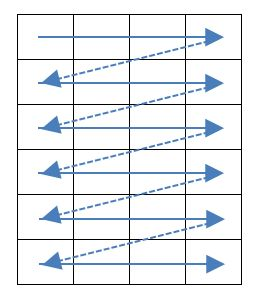

だいたい+x-yなのであまり気にしてません。

国土地理院以外でやるなら見ておく必要がありそうです。

disp(T.DEM.coverage.gml_coverageFunction.gml_GridFunction.gml_sequenceRule.orderAttribute)

+x-y


### グリッドセルの開始点

startPointに入ってます。

**こいつが本間に厄介です。(0, 0])からスタートしない場合もあります！**

**実際のデータ数が(low + 1)×(high + 1)に必ずしもならないことに注意です！**

disp(T.DEM.coverage.gml_coverageFunction.gml_GridFunction.gml_startPoint)

0 414


FG-GML-5841-46-00-DEM1A-20230929.xmlでも(0, 414)からスタートしてますね…

今回はstartPoint がゼロスタートでない場合はNaNで埋めることにします。

ツールによっては-9999mをNaNとして認識するものもあるらしいのですがMATLABはそうじゃないそうです(MathWorks情報)。

## GeoTiff変換しよう

先の情報がわかればGeoTiff変換は簡単です。

[georefcells](https://jp.mathworks.com/help/map/ref/georefcells.html) に緯度, 経度, 標高データを入れて、[geotiffwrite](https://jp.mathworks.com/help/map/ref/geotiffwrite.html) で書き出すだけです。

### 変換用コード

clear,clc,close all;
% path = '\PackDLMap\FG-GML-5841-46-DEM1A';

% 任意のフォルダを選択
path = uigetdir;

tmpファイルを作成しGeoTiff化したファイルを入れます。

if ~exist(fullfile(path,'tmp'))
    mkdir(path, 'tmp')
end

ひとつずつ変換します。ファイルの数だけループします。

流石に重たいので [parfor](https://jp.mathworks.com/help/matlab/ref/parfor.html) で並列処理します。

fnames = dir(fullfile(path,"*.xml"));
path = fnames(1).folder;
file = {fnames.name}';

fsize =  length(file);
parfor ii = 1:fsize
    file_name = fullfile(path,file{ii});
    MyGeoTIFFConvert(file_name);
end

'Processes' プロファイルを使用して並列プール (parpool) を起動中...
6 個のワーカーをもつ並列プールに接続されています。


終わったらメンションします。

disp('GeoTIFF変換完了')

GeoTIFF変換完了


### GeoTiff変換用の関数

function [] = MyGeoTIFFConvert(file_name)
% 参考：https://qiita.com/tobira-code/items/43a23362f356198adce2
% 出力用に名前を保存
    [fpath, name, ~] = fileparts(file_name);
    name = string(strsplit(name,'-'));
    name = strjoin(name(3:5),'');

    % 緯度軽度：これをもとにGeoTiffに変換
    T = readstruct(file_name,'FileType','xml');
    T = T.DEM.coverage;
    LatLon  = struct2array(T.gml_boundedBy.gml_Envelope)';
    LatLon  = LatLon(2:end);
    LatLon  = double(split(LatLon))';

    % DataBlock：各グリッドセルの標高データ
    Raster  = splitlines(T.gml_rangeSet.gml_DataBlock.gml_tupleList);
    Raster  = str2double(extractAfter(Raster,','));

    % GridEnvelope：メッシュを構成するグリッドセルの配列数
    GridEnvelope = struct2array(T.gml_gridDomain.gml_Grid.gml_limits.gml_GridEnvelope)';
    GridEnvelope = double(split(GridEnvelope));

    % startPoint：グリッドセルの開始点を指定
    StartPoint   = str2double(strsplit(T.gml_coverageFunction.gml_GridFunction.gml_startPoint))+1;

    % サイズ
    RasterSize   = diff(GridEnvelope) + 1;
    RasterLength = prod(RasterSize);

    % startPointが0スタートでない場合、NaNで埋める
    % MATLABではNaNで出力するのがいいらしい(-9999mをNaNとして認識できない)
    if length(Raster) == RasterLength
        idx = isnan(Raster);
        % Raster(idx) = -9999;
        Raster(idx) = NaN;
        RasterMap = reshape(Raster,RasterSize)';
    else
        StartPoint = prod(StartPoint);
        tmp = nan(RasterLength,1);
        tmp(StartPoint:StartPoint+length(Raster)-1) = Raster;
        idx = isnan(tmp);
        % tmp(idx) = -9999;
        tmp(idx) = NaN;
        RasterMap = reshape(tmp,RasterSize)';
    end

    % GeoTiffファイルとして書き出し
    % EPSGコードは日本だと6668
    R = georefcells(LatLon(1,:), LatLon(2,:), flip(RasterSize),"ColumnsStartFrom","north");
    geotiffwrite(fullfile(fpath,'tmp',strjoin([name,'.tif'],'')),single(RasterMap),R,"CoordRefSysCode",'EPSG:6668')
end

## できたものを見てみよう

さすがに [RoadRunner](https://jp.mathworks.com/products/roadrunner.html) で確認なんてできませんので、フリーソフト [QGIS](https://qgis.org/ja/site/) で確認します。

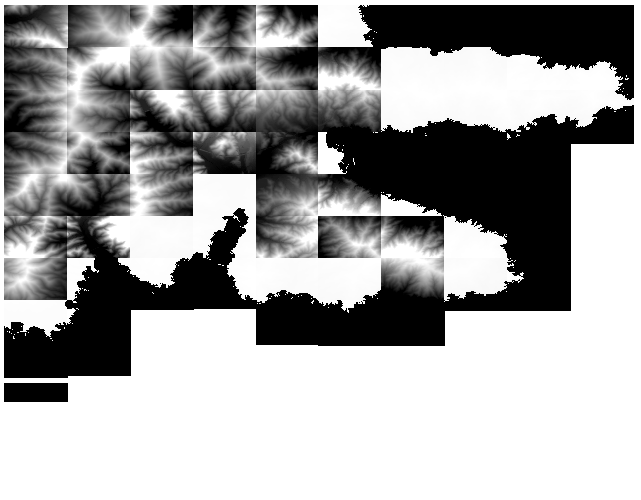

そう、これでは2次メッシュがきれいに繋がらないんですよねー

欠損があったり境界部がきれいにつながってなかったり…

## おわりに

今回は国土地理院のDEMデータについて中身をだいたい理解してGeoTiffファイルにしました。

次回はモザイク結合で2次メッシュデータをきれいに繋げます。

## 参考

- [RoadRunner:日本の空中写真・標高データ活用法](https://jp.mathworks.com/videos/roadrunner-how-to-import-japanese-aerial-and-elevation-images-1629895701730.html)

- [総務省統計局：地域メッシュ統計](https://www.stat.go.jp/data/mesh/index.htm)

- [基盤地図情報～数値標高モデルを利用する](https://qiita.com/tobira-code/items/43a23362f356198adce2)

- [pythonで地域メッシュごとのポリゴンデータからGeoTIFFを作成する：国土数値情報平年メッシュデータを例に](https://computational-sediment-hyd.hatenablog.jp/entry/2022/11/19/000000)